generic genetic algo

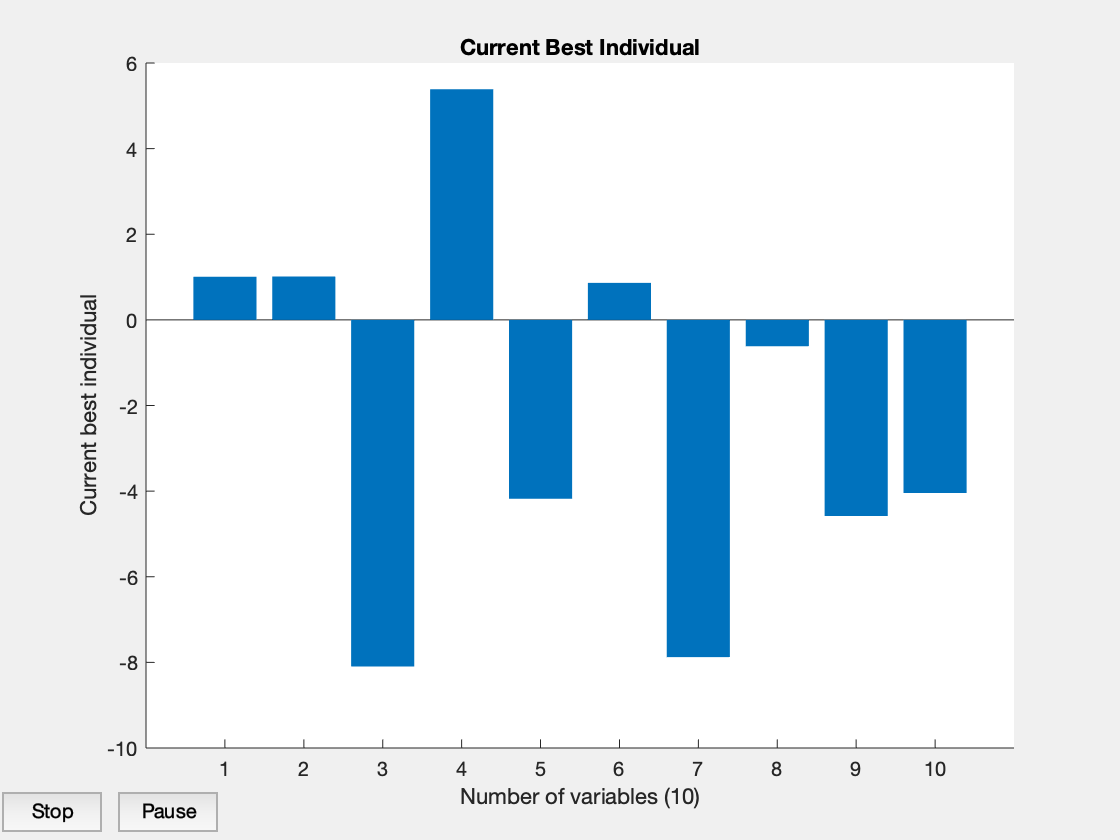

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


xvec1 =     1.0069    1.0139   -8.0961    5.3859   -4.1772    0.8632   -7.8764   -0.6164   -4.5825   -4.0450


fvalvec1 = 4.7677e-05

exitflagvec1 = 1

outputvec1 = struct with fields:
      problemtype: 'boundconstraints'
         rngstate: [1×1 struct]
      generations: 59
        funccount: 11420
          message: 'Optimization terminated: average change in the fitness value less than options.FunctionTolerance.'
    maxconstraint: 0


populationvec1 =     1.0069    1.0139   -8.0961    5.3859   -4.1772    0.8632   -7.8764   -0.6164   -4.5825   -4.0450
    1.0069    1.0139   -8.3563    2.9678   -0.9014    0.8632   -7.8764   -0.6164   -4.5845   -4.0450
    1.0069    1.0139   -8.0961    5.3885   -4.1772    6.7546   -7.8764   -0.6164   -4.5845   -0.2803
    1.0069    1.0139   -8.0953    5.3859   -4.0615    0.8632   -2.4353   -0.6164   -4.5825   -4.0469
    1.0069    1.0139   -8.0961    5.3859   -4.0615    0.8632   -2.4353   -0.6164   -4.5845   -4.0469
    1.0069    1.0139   -8.0953    5.3859   -4.0615    0.8632   -2.4323    8.4289   -4.5845   -4.0450
    1.0069    1.0139   -8.0961    5.3885   -4.1772    6.7546   -7.8764   -0.6164   -4.5845   -0.2803
    1.0069    1.0139   -8.0961    5.3859   -4.1772    0.8632   -2.4331    7.8633   -4.5845   -4.0450
    1.0069    1.0139   -8.0953    5.3885   -4.1772    6.7546   -7.8764   -0.6164   -4.5845   -0.2803
    1.0069    1.0139   -8.0953    5.3885   -4.0615    6.7546   -7.8764   -

scorevec1 = 	1.0e+-4 *

    0.4768
    0.4768
    0.4768
    0.4768
    0.4768
    0.4768
    0.4768
    0.4768
    0.4768
    0.4768


nvars=10;
lb = [0,0];
ub = [3,3];
popsize=100;

option = optimoptions('ga');
%option = optimoptions(option, 'PopulationType',"bitstring");
initial = optimoptions(option, 'InitialPopulationMatrix', popsize);

option1 = optimoptions(option,'PlotFcn','gaplotbestindiv');
option2 = optimoptions(option,'PlotFcn',{@gaplotbestf,@gaplotchange});

vectorizedoption = optimoptions(option,'UseVectorized',true);

rng(100)

[xvec1,fvalvec1,exitflagvec1,outputvec1,populationvec1,scorevec1] = ga(@(x) vectorized_fitness(x,100,1),nvars,[],[],[],[],lb,ub,[],option1)

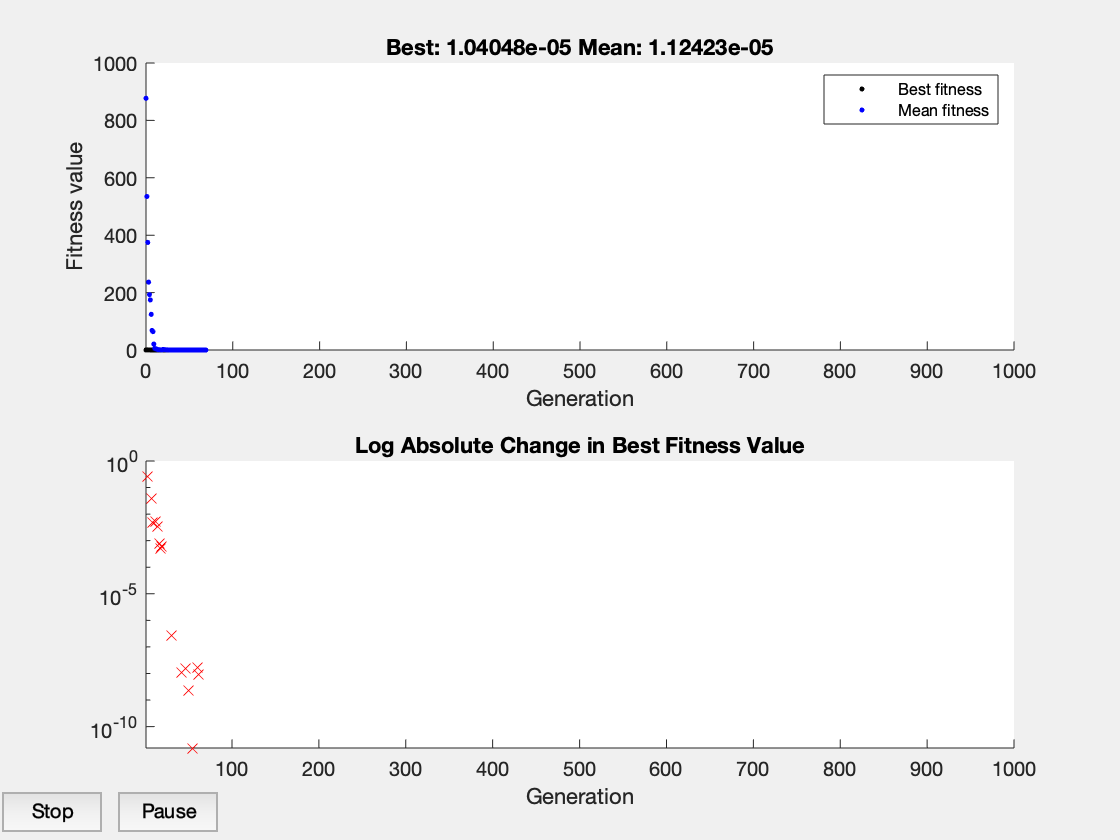

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


xvec2 =     1.0032    1.0065   -3.3887    6.9520    8.7707   -7.8571    6.3222    3.7144   -8.6522    7.5084


fvalvec2 = 1.0405e-05

exitflagvec2 = 1

outputvec2 = struct with fields:
      problemtype: 'boundconstraints'
         rngstate: [1×1 struct]
      generations: 69
        funccount: 13320
          message: 'Optimization terminated: average change in the fitness value less than options.FunctionTolerance.'
    maxconstraint: 0


populationvec2 =     1.0032    1.0065   -3.3887    6.9520    8.7707   -7.8571    6.3222    3.7144   -8.6522    7.5084
    1.0032    1.0065   -3.3887    6.9520    8.7707   -7.8571    6.3222    3.7144   -8.6521    7.5084
    1.0032    1.0065   -3.3887    6.9520    8.7708   -7.8571    6.3222    3.7144   -8.6522    7.5084
    1.0032    1.0065   -3.3887    6.9519    8.7708   -7.8571    6.3222    3.7142   -8.6519    7.5083
    1.0032    1.0065   -3.3886    6.9520    8.7707   -7.8571    6.3222    3.7144   -8.6521    7.5085
    1.0032    1.0065   -3.3887    6.9520    8.7707   -7.8570    6.3222    3.7144   -8.6521    7.5084
    1.0032    1.0065   -3.3887    6.9522    8.7707   -7.8571    6.3222    3.7142   -8.6519    7.5083
    1.0032    1.0065   -3.3887    6.9519    8.7708   -7.8570    6.3221    3.7142   -8.6522    7.5084
    1.0032    1.0065   -3.3887    6.9520    8.7707   -7.8571    6.3222    3.7144   -8.6522    7.5085
    1.0032    1.0065   -3.3887    6.9520    8.7707   -7.8570    6.3222    

scorevec2 = 	1.0e+-4 *

    0.1040
    0.1040
    0.1040
    0.1040
    0.1040
    0.1040
    0.1040
    0.1040
    0.1040
    0.1040


[xvec2,fvalvec2,exitflagvec2,outputvec2,populationvec2,scorevec2] = ga(@(x) vectorized_fitness(x,100,1),nvars,[],[],[],[],lb,ub,[],option2)

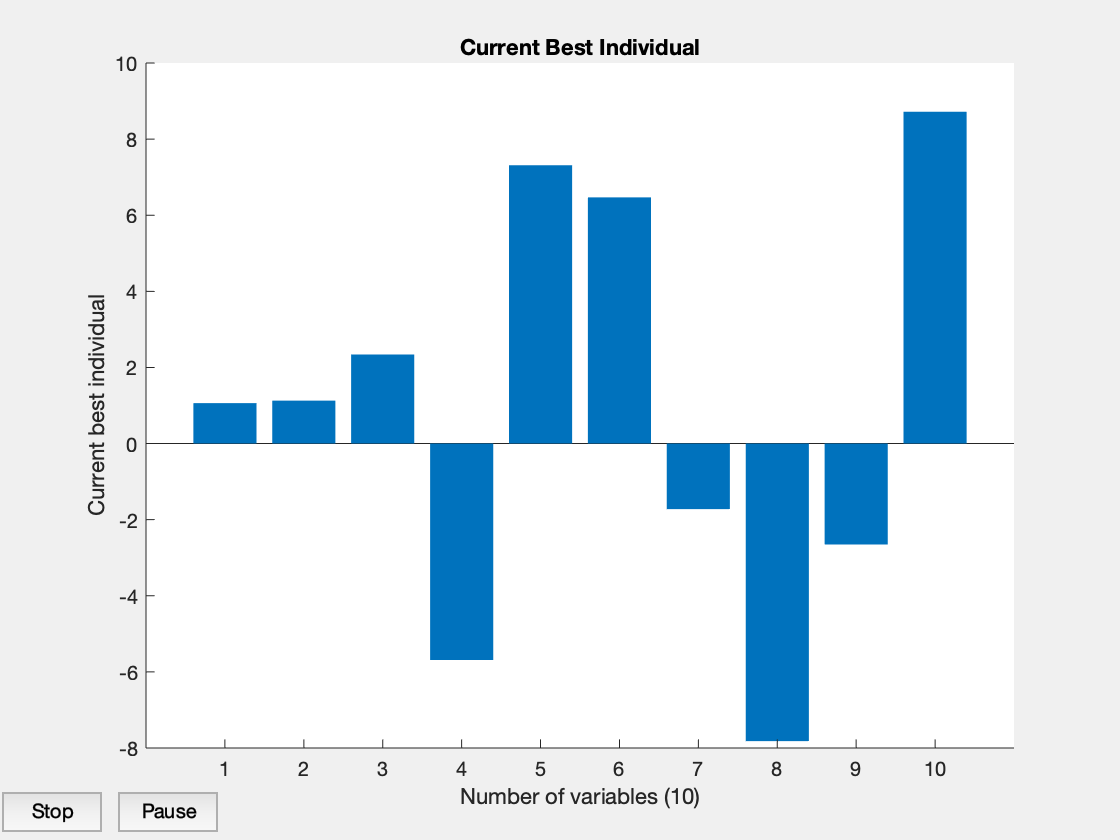

Optimization terminated: maximum number of generations exceeded.


xsimp1 =     1.0617    1.1276    2.3404   -5.6866    7.3140    6.4681   -1.7226   -7.8207   -2.6537    8.7202


fvalsimp1 = 0.0038

exitflagsimp1 = 0

outputsimp1 = struct with fields:
      problemtype: 'boundconstraints'
         rngstate: [1×1 struct]
      generations: 1000
        funccount: 190210
          message: 'Optimization terminated: maximum number of generations exceeded.'
    maxconstraint: 0


populationsimp1 =     1.0619    1.1276    2.3404   -5.6865    7.3143    6.4681   -1.7226   -7.8207   -2.6537    8.7202
    1.0619    1.1277    2.3405   -5.6840    7.3140    6.4681   -1.7213   -7.8206   -2.6543    8.7205
    1.0617    1.1277    2.3404   -5.6866    7.3140    6.4681   -1.7227   -7.8207   -2.6537    8.7202
    1.0619    1.1277    2.3404   -5.6840    7.3140    6.4681   -1.7216   -7.8209   -2.6543    8.7203
    1.0619    1.1277    2.3406   -5.6842    7.3140    6.4681   -1.7225   -7.8209   -2.6543    8.7203
    1.0619    1.1277    2.3406   -5.6842    7.3140    6.4681   -1.7216   -7.8209   -2.6543    8.7204
    1.0619    1.1277    2.3404   -5.6866    7.3140    6.4681   -1.7227   -7.8207   -2.6537    8.7202
    1.0619    1.1277    2.3406   -5.6842    7.3140    6.4681   -1.7220   -7.8209   -2.6543    8.7202
    1.0619    1.1277    2.3404   -5.6840    7.3140    6.4681   -1.7217   -7.8209   -2.6543    8.7203
    1.0619    1.1277    2.3404   -5.6840    7.3140    6.4679   -1.7216   

scoresimp1 =     0.0038
    0.0038
    0.0038
    0.0038
    0.0038
    0.0038
    0.0038
    0.0038
    0.0038
    0.0038



[xsimp1,fvalsimp1,exitflagsimp1,outputsimp1,populationsimp1,scoresimp1] = ga(@simple_fitness,nvars,[],[],[],[],lb,ub,[],option1)

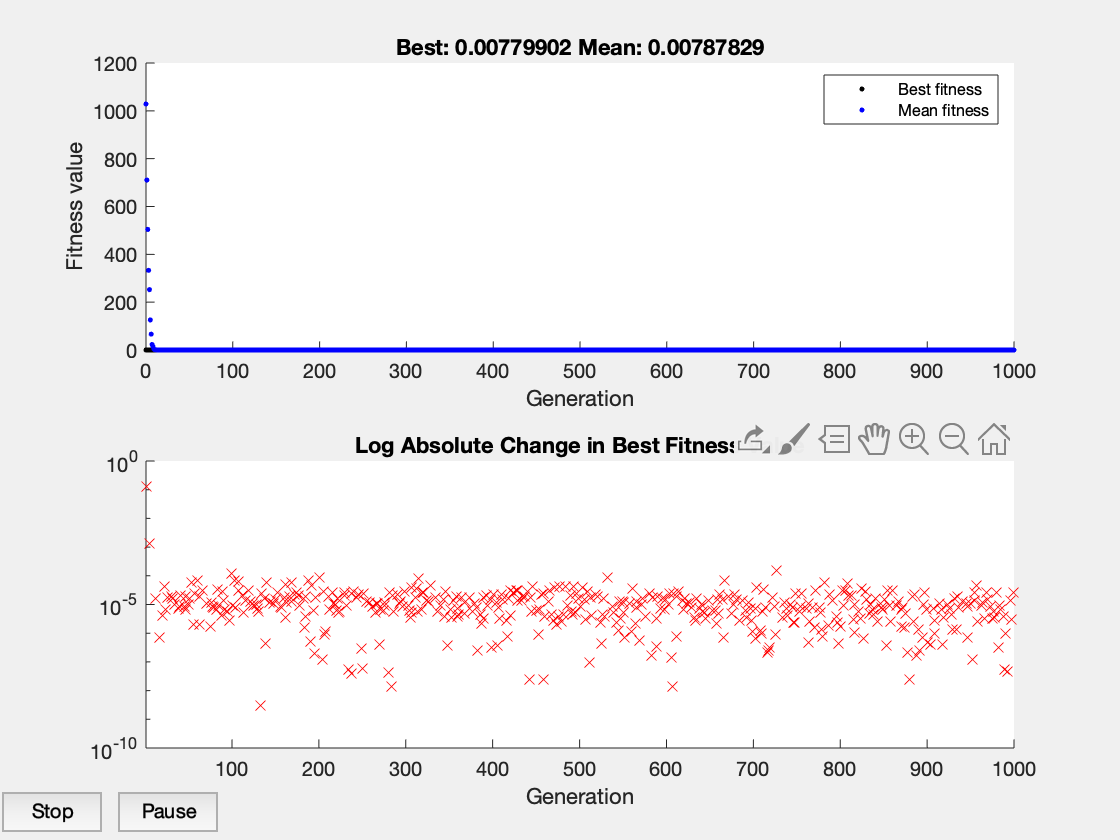

Optimization terminated: maximum number of generations exceeded.


xsimp2 =     1.0883    1.1844    3.9428    1.8792    7.0133   -1.8945   -6.6723    6.7379    8.4877   -0.3622


fvalsimp2 = 0.0078

exitflagsimp2 = 0

outputsimp2 = struct with fields:
      problemtype: 'boundconstraints'
         rngstate: [1×1 struct]
      generations: 1000
        funccount: 190210
          message: 'Optimization terminated: maximum number of generations exceeded.'
    maxconstraint: 0


populationsimp2 =     1.0883    1.1844    3.9428    1.8792    7.0133   -1.8945   -6.6723    6.7379    8.4877   -0.3622
    1.0884    1.1845    3.9428    1.8789    7.0124   -1.8954   -6.6726    6.7380    8.4873   -0.3607
    1.0883    1.1849    3.9428    1.8789    7.0133   -1.8946   -6.6723    6.7379    8.4873   -0.3623
    1.0883    1.1849    3.9428    1.8789    7.0133   -1.8954   -6.6723    6.7379    8.4873   -0.3623
    1.0883    1.1849    3.9428    1.8789    7.0121   -1.8946   -6.6723    6.7379    8.4873   -0.3623
    1.0883    1.1849    3.9428    1.8787    7.0121   -1.8946   -6.6714    6.7378    8.4873   -0.3623
    1.0883    1.1849    3.9428    1.8789    7.0133   -1.8946   -6.6723    6.7370    8.4873   -0.3623
    1.0883    1.1849    3.9424    1.8789    7.0121   -1.8954   -6.6723    6.7378    8.4873   -0.3623
    1.0883    1.1849    3.9428    1.8789    7.0121   -1.8946   -6.6714    6.7379    8.4873   -0.3623
    1.0883    1.1849    3.9428    1.8789    7.0133   -1.8946   -6.6714   

scoresimp2 =     0.0078
    0.0078
    0.0078
    0.0078
    0.0078
    0.0078
    0.0078
    0.0078
    0.0078
    0.0078


[xsimp2,fvalsimp2,exitflagsimp2,outputsimp2,populationsimp2,scoresimp2] = ga(@simple_fitness,nvars,[],[],[],[],lb,ub,[],option2)